# Neural Network Classification 3

In this lab sheet we'll look at how to use pre-built deep-learning model for image-classification. As prerequisites, this script assumes you have completed:

- The Matlab Fundamentals materials.

- The KNN lab

- The image-processing labs

- The first neural network lab

## Loading and preparing datasets

The following steps should all be familiar from the  k-NN and NN labs. Refer back to them if you're not sure about any of the steps.

Read the MerchData dataset and split it into training and testing sets, with 60% of each type of object in training:

clear;  % this just removes all the previous variables, please don't remove it.

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% write your code on the lines below:

% SOLUTION:

 % Locate the digit images 
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

% Load them into a image store. This includes labels etc.
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');




% We'll need the number of different labels for the network
numLabels = length(unique(sort(imds.Labels)));
% we will need the number of rows and columns of the images in the network
% Note that we can obtain any image by using its index

% we will need the number of rows and columns of the images in the network

imageSize = size(readimage(imds,1));


rng(0);

[training, testing] = splitEachLabel(imds,0.60,'randomize');



## Building a CNN

Build a CNN of the data. Use the same trainign options as in tasks8, but set the validation patience to 3 and frequency to 1 (you may want to look at the manual for how to do this). Use the same set of layers as in tasks8, but note that we are using colopur images, not gray-scale, and remove the fullyConnectedLayer(15). 

%trainLabels = training.Labels;
%testLabels = testing.Labels;

augTrain = augmentedImageDatastore(imageSize, training, 'ColorPreprocessing', 'gray2rgb');
augTest = augmentedImageDatastore(imageSize, testing, 'ColorPreprocessing', 'gray2rgb');


options = trainingOptions('sgdm', ...
    'MaxEpochs',16, ...
    'InitialLearnRate',0.005, ...
    'ValidationData',augTest,...
    'ValidationFrequency',1,...
    'ValidationPatience',3, ...
    'Verbose',true, ...
    'VerboseFrequency',30, ...
    'Plots','training-progress',...
    'ExecutionEnvironment', 'auto');

% then set the model up...
layers = [
            imageInputLayer([imageSize 3])

            convolution2dLayer(3,15,'Padding',1)
            batchNormalizationLayer
            reluLayer

            maxPooling2dLayer(2,'Stride',2)

            %convolution2dLayer(5,20,'Padding',2)
            %batchNormalizationLayer
            %reluLayer
            %fullyConnectedLayer(15)

            fullyConnectedLayer(numLabels)
            softmaxLayer
            classificationLayer];

[net3,info] = trainNetwork(augTrain,layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       11.72% |       14.65% |       2.9563 |       2.6200 |          0.0050 |
|       1 |           2 |       00:00:08 |       16.41% |       15.90% |       2.5009 |       2.5034 |          0.0050 |
|       1 |           3 |       00:00:08 |       12.50% |       16.65% |       2.5760 |       2.5004 |          0.0050 |
|       1 |           4 |       00:00:09 |       13.28% |       18.95% |       2.6816 |   

% Now use the network to infer the labels of the training images
pred3_train_labels = classify(net3,augTrain);
% and also of the validation set
pred3_test_labels = classify(net3,augTest);

% Obtain a confusion matrix of the labels (i.e. the counts of each
% (inferred,real) label combination for the two datasets
[confusion3_train,order_train] = confusionmat(training.Labels, pred3_train_labels);
[confusion3_test,order_test] = confusionmat(testing.Labels, pred3_test_labels);
% And finally display the accuracy of the classifier (i.e. the fraction of
% images which are correctly labeled by the net.
disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_train))/sum(sum(confusion3_train))* 100) ;

   71.6167



disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_test))/sum(sum(confusion3_test))* 100) ;

   69.8000



Measure the accuracy with which the net can classify the training and  testing images. I get 1.0 and 0.7 respectively. I haven't tuned the network at all - it might be improved, but performance will always be limited by the small size of the training set.

%Solution:


Now view the weights of the first layer of kernels in the net. There should be 30 of them, so use a subplot command to draw a of small images. They are colour patches with ranges 0-1, and imshow will want integers, so scale them to 0 - 255. You can explore the structure of the network by displaying it.

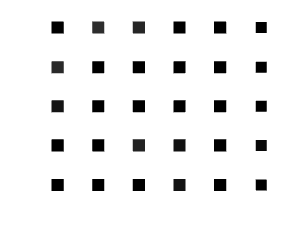

% Solution:
% get the weights
lay = net3.Layers(2,1).Weights();

OutImage = uint8(255 * lay(:,:,:));

for i = 1 : 30
    subplot(5,6,i);
    
    imshow(OutImage(i))
    % imShow each of them here...
end

## Encode the images on a pre-trained model

Load a pre-trained network (vgg16) and take a look at how it is designed. How many layers does it have, and how many outputs does it generate? Take a look at Pretrained Deep Neural Networks in the Matlab manual to see the range of models possible.

net2 = alexnet;
deepNetworkDesigner(net2);

The net may not be the same size as the images we want to pass through it  - augmentedImageDatastore will change the size.

inputSize = net2.Layers(1).InputSize;
augTrain = augmentedImageDatastore(inputSize(1:2),training,'ColorPreprocessing', 'gray2rgb');
augTest = augmentedImageDatastore(inputSize(1:2),testing,'ColorPreprocessing', 'gray2rgb');

% Now get the activation levels for the last layer of the last FC of the net for the data
layer = 'fc8';
featuresTrain = activations(net2,augTrain,layer,'OutputAs','rows');
featuresTest = activations(net2,augTest,layer,'OutputAs','rows');

Now build a KNN from the features obtained from the fc8 network - this is intended as a reference...

% Solution:
train_labels = training.Labels;
test_labels = testing.Labels;

kNN = fitcknn(featuresTrain, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, featuresTest);

[c, order] = confusionmat(test_labels, predictions);
   
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 99.8750


pred_test2_labels = classify(net2,augTest);


% Find incorrect images:
wrong1 = find(pred_test2_labels~=testing.Labels);
if (~isempty(wrong1))
    for i = 1 : length(wrong1)
        testing.Labels(wrong1(i));
        pred_test2_labels(wrong1(i));
        wrongIm= testing.readimage(wrong1(i));
        %figure;
        %imshow(wrongIm);
    end
end


Build a FNN (i.e. a Fully-connected Neural Network) to describe the features. Validate on the testing features (and labels), use [200 50] as layer sizes. Get the classification accuracy on the trainig and test images and display any incorrect ones:

## Augment the images

A typical way of improving performance is to augment the images by scaling, rotating them etc:

augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1.5], ...
    'RandXReflection', 1, ...
    'RandYReflection', 1, ...
    'RandXTranslation', [-20 20], ...
    'RandYTranslation', [-20 20]');

aug = augmentedImageDatastore(inputSize(1:2),training,testing,'DataAugmentation',augmenter);
%augTest2 = augmentedImageDatastore(inputSize(1:2),testing,'DataAugmentation',augmenter,'ColorPreprocessing', 'gray2rgb');


Now get the activations as before and train and test another FNN of the same size. 



layers = [
    imageInputLayer(imageSize)
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'MaxEpochs',16, ...
    'InitialLearnRate',0.005, ...
    'ValidationData',{x,y},...
    'ValidationFrequency',1,...
    'ValidationPatience',3, ...
    'Verbose',true, ...
    'VerboseFrequency',30, ...
    'Plots','training-progress',...
    'ExecutionEnvironment', 'auto');

net = trainNetwork(augimds,layers,opts);

layer ='fc8';
%net2.Layers
featuresTrain2 = activations(net2,aug,layer,'OutputAs','rows');
featuresTest2 = activations(net2,aug,layer,'OutputAs','rows');

[net,info] = trainNetwork(featuresTrain2,layers,options);
% Now use the network to infer the labels of the training images
pred3_train_labels = classify(net,featuresTrain2);
% and also of the validation set
pred3_test_labels = classify(net,featuresTest2);

% Obtain a confusion matrix of the labels (i.e. the counts of each
% (inferred,real) label combination for the two datasets
[confusion3_train,order_train] = confusionmat(training.Labels, pred3_train_labels);
[confusion3_test,order_test] = confusionmat(testing.Labels, pred3_test_labels);
% And finally display the accuracy of the classifier (i.e. the fraction of
% images which are correctly labeled by the net.
disp('Training accuracy : ');
disp(sum(diag(confusion3_train))/sum(sum(confusion3_train))* 100);
disp('Training accuracy : ');
disp(sum(diag(confusion3_test))/sum(sum(confusion3_test))* 100);


## Extension - other models

If you look at Pretrained Deep Neural Networks in the Matlab manual, you'll see that there are a range of different models available. Try encoding your images on some others (in particular vgg16) and also on some lower levels within the nets. Performance may go up or down.

--If your data is very similar to the original data, then the more specific features extracted deeper in the network are likely to be useful for the new task.

--If your data is very different from the original data, then the features extracted deeper in the network might be less useful for your task. Try training the final classifier on more general features extracted from an earlier network layer. If the new data set is large, then you can also try training a network from scratch.

net = vgg16

net.Layers
